# 4.7 Design a SS controller selecting the poles using the LQR technique

load Linear_Param.mat
Cweight = [5 1 10 2]; %Most weight on theta_b, then on x_w, least on velocities
B1 = B(:,1);
[num,den] = ss2tf(A,B1,Cweight,0)

num =             0  -1.5948e+02  -7.9740e+02  -7.2702e+02  -3.6351e+03


den =    1.0000e+00   4.7501e+02  -6.2019e+01  -1.5371e+04            0


s = tf("s");
Nplus = num(1)*(s)^4 +num(2)*(s)^3 +num(3)*(s)^2 +num(4)*(s)^1 +num(5)*(s)^0;
Nminus = num(1)*(-s)^4 +num(2)*(-s)^3 +num(3)*(-s)^2 +num(4)*(-s)^1 +num(5)*(-s)^0;
Dplus = den(1)*(s)^4 +den(2)*(s)^3 +den(3)*(s)^2 +den(4)*(s)^1 +den(5)*(s)^0;
Dminus = den(1)*(-s)^4 +den(2)*(-s)^3 +den(3)*(-s)^2 +den(4)*(-s)^1 +den(5)*(-s)^0;
sysGG = Nplus*Nminus/(Dplus*Dminus)

sysGG =
 
  -2.543e04 s^6 + 4.04e05 s^4 + 5.269e06 s^2 + 1.321e07
  -----------------------------------------------------
    s^8 - 2.258e05 s^6 + 1.461e07 s^4 - 2.363e08 s^2
 
Continuous-time transfer function.
Model Properties


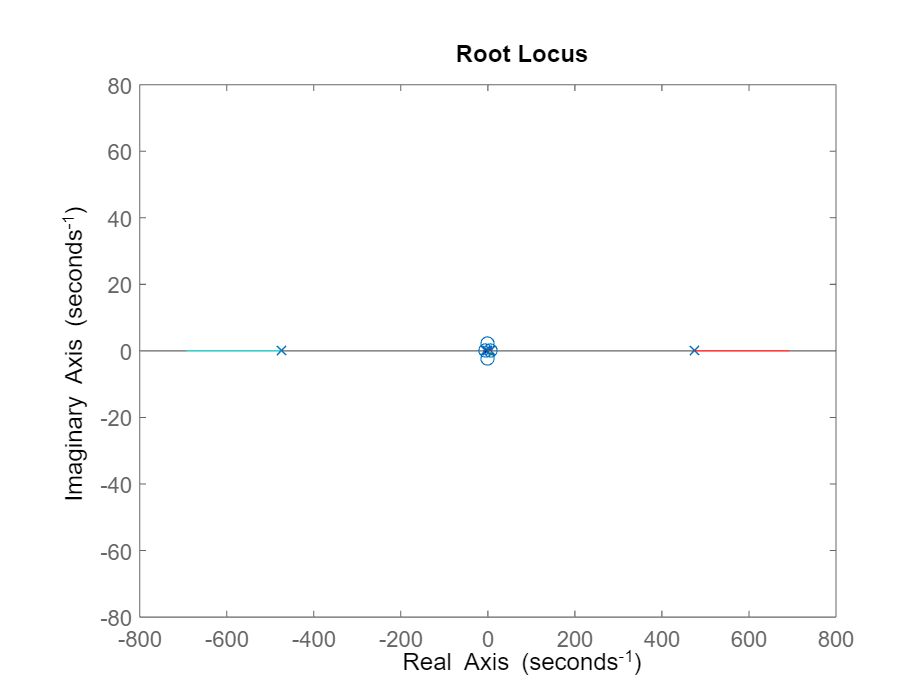

rho = linspace(0,10);
rlocus(sysGG,rho)

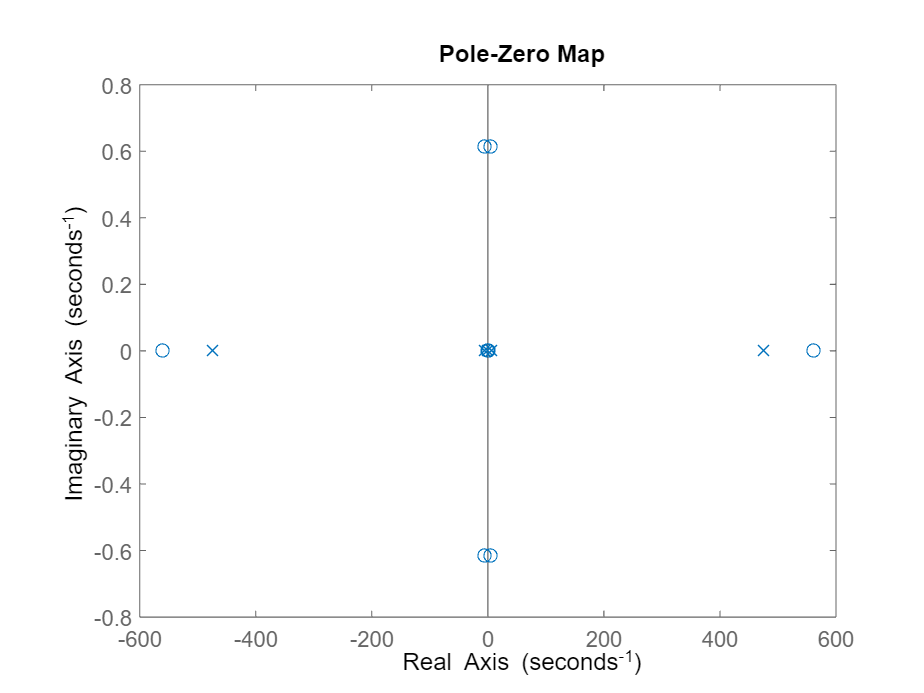


rhoChose = 3.5;
  pzmap(1+rhoChose*sysGG)

poles =  zero(1+rhoChose*sysGG);
stablePoles = poles(real(poles)<0)

stablePoles =   -5.6100e+02 + 0.0000e+00i
  -5.0716e+00 + 6.1529e-01i
  -5.0716e+00 - 6.1529e-01i
  -4.6445e-01 + 0.0000e+00i


K = acker(A,B1,stablePoles)

K =   -9.3541e+00  -4.4935e+01  -6.9271e+01  -1.1343e+01
